clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[7.905;1.432;2.731];
u31=[0.7849;0.2129;0.5819];
r2=[-1.094;5.506;8.660];
u32=[-0.7849;0.2129;-0.5819];
r3=[7.905;-6.716;2.731];
u33=[0.7849;0.2129;0.5819];
r4=[11.677;5.506;8.660];
u34=[-0.7849;0.2129;-0.5819];
r5=[13.865;1.432;-8.660];
u35=[0.7849;0.2129;0.5819];
r6=[4.866;5.506;-2.731];
u36=[-0.7849;0.2129;-0.5819];



x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];
x8=[];
y8=[];
x9=[];
y9=[];
x10=[];
y10=[];
x11=[];
y11=[];

hold on 
axis([0 15 0 15]);
for R1=10:-0.3:6 %离心率
    R3=3;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =    10.0000    0.9000    1.0026


ans =     9.7000    1.0500    1.0121


ans =     9.4000    1.2500    1.0019


ans =     9.1000    1.4000    1.0042


ans =     8.8000    1.5500    1.0050


ans =     8.5000    1.7000    1.0055


ans =     8.2000    1.8500    1.0070


ans =     7.9000    2.0000    1.0107


ans =     7.6000    2.2000    1.0034


ans =     7.3000    2.4000    1.0034


ans =     7.0000    2.6500    1.0006


ans =     6.7000    2.9500    1.0013


ans =     6.4000    3.3500    1.0043


ans =     6.1000    4.0500    1.0006



for R3=4:0.3:13 %离心率
    R1=3;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     6.1000    4.0000    1.0052


ans =     6.0000    4.3000    1.0071


ans =     5.9000    4.6000    1.0144


ans =     5.8500    4.9000    1.0112


ans =     5.8000    5.2000    1.0110


ans =     5.7500    5.5000    1.0133


ans =     5.7500    5.8000    1.0019


ans =     5.7000    6.1000    1.0077


ans =     5.6500    6.4000    1.0151


ans =     5.6500    6.7000    1.0073


ans =     5.6500    7.0000    1.0003


ans =     5.6000    7.3000    1.0105


ans =     5.6000    7.6000    1.0048


ans =     5.5500    7.9000    1.0165


ans =     5.5500    8.2000    1.0117


ans =     5.5500    8.5000    1.0073


ans =     5.5500    8.8000    1.0032


ans =     5.5000    9.1000    1.0167


ans =     5.5000    9.4000    1.0131


ans =     5.5000    9.7000    1.0097


ans =     5.5000   10.0000    1.0066


ans =     5.5000   10.3000    1.0035


ans =     5.5000   10.6000    1.0007


ans =     5.4500   10.9000    1.0155


ans =     5.4500   11.2000    1.0128


ans =     5.4500   11.5000    1.0103


ans =     5.4500   11.8000    1.0079


ans =     5.4500   12.1000    1.0055


ans =     5.4500   12.4000    1.0033


ans =     5.4500   12.7000    1.0011


ans =     5.4000   13.0000    1.0167



for R1=13:-0.3:8 %离心率
    R3=1;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans =    13.0000    0.9000    1.0227


ans =    12.7000    0.9000    1.0272


ans =    12.4000    0.9000    1.0320


ans =    12.1000    0.9000    1.0372


ans =    11.8000    0.9000    1.0427


ans = 1×3
   11.5000    0.9000    1.0487


ans = 1×3
   11.2000    0.9000    1.0552


ans = 1×3
   10.9000    0.9000    1.0623


ans = 1×3
   10.6000    0.9000    1.0699


ans = 1×3
   10.3000    0.9000    1.0782


ans = 1×3
   10.0000    0.9000    1.0873


ans = 1×3
    9.7000    0.9500    1.0021


ans = 1×3
    9.4000    0.9500    1.0130


ans = 1×3
    9.1000    0.9500    1.0250


ans = 1×3
    8.8000    0.9500    1.0383


ans = 1×3
    8.5000    0.9500    1.0530


ans = 1×3
    8.2000    0.9500    1.0693


for R3=1:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans = 1×3
    7.9500    1.0000    1.0031


ans = 1×3
    5.3000    1.3000    1.0092


ans = 1×3
    4.7000    1.6000    1.0112


ans = 1×3
    4.4500    1.9000    1.0086


ans = 1×3
    4.3000    2.2000    1.0124


ans = 1×3
    4.2000    2.5000    1.0186


ans = 1×3
    4.1500    2.8000    1.0160


ans = 1×3
    4.1000    3.1000    1.0209


ans = 1×3
    4.1000    3.4000    1.0077


ans = 1×3
    4.0500    3.7000    1.0210


ans = 1×3
    4.0500    4.0000    1.0130


ans = 1×3
    4.0500    4.3000    1.0067


ans = 1×3
    4.0500    4.6000    1.0016


ans = 1×3
    4.0000    4.9000    1.0217


ans = 1×3
    4.0000    5.2000    1.0181


ans = 1×3
    4.0000    5.5000    1.0152


ans = 1×3
    4.0000    5.8000    1.0127


ans = 1×3
    4.0000    6.1000    1.0105


ans = 1×3
    4.0000    6.4000    1.0087


ans = 1×3
    4.0000    6.7000    1.0071


ans = 1×3
    4.0000    7.0000    1.0057


ans = 1×3
    4.0000    7.3000    1.0044


ans = 1×3
    4.0000    7.6000    1.0033


ans = 1×3
    4.0000    7.9000    1.0024


ans = 1×3
    4.0000    8.2000    1.0015


ans = 1×3
    4.0000    8.5000    1.0007


ans = 1×3
    4.0000    8.8000    1.0000


ans = 1×3
    3.9500    9.1000    1.0246


ans = 1×3
    3.9500    9.4000    1.0241


ans = 1×3
    3.9500    9.7000    1.0235


ans = 1×3
    3.9500   10.0000    1.0231


ans = 1×3
    3.9500   10.3000    1.0226


ans = 1×3
    3.9500   10.6000    1.0222


ans = 1×3
    3.9500   10.9000    1.0219


ans = 1×3
    3.9500   11.2000    1.0216


ans = 1×3
    3.9500   11.5000    1.0212


ans = 1×3
    3.9500   11.8000    1.0210


ans = 1×3
    3.9500   12.1000    1.0207


ans = 1×3
    3.9500   12.4000    1.0204


ans = 1×3
    3.9500   12.7000    1.0202


ans = 1×3
    3.9500   13.0000    1.0200



for R3=13:-0.3:6 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans = 1×3
    1.7500   13.0000    1.0025


ans = 1×3
    1.7500   12.7000    1.0204


ans = 1×3
    1.8000   12.4000    1.0038


ans = 1×3
    1.8000   12.1000    1.0229


ans = 1×3
    1.8500   11.8000    1.0086


ans = 1×3
    1.8500   11.5000    1.0291


ans = 1×3
    1.9000   11.2000    1.0169


ans = 1×3
    1.9500   10.9000    1.0062


ans = 1×3
    1.9500   10.6000    1.0282


ans = 1×3
    2.0000   10.3000    1.0191


ans = 1×3
    2.0500   10.0000    1.0112


ans = 1×3
    2.1000    9.7000    1.0043


ans = 1×3
    2.1000    9.4000    1.0283


ans = 1×3
    2.1500    9.1000    1.0228


ans = 1×3
    2.2000    8.8000    1.0182


ans = 1×3
    2.2500    8.5000    1.0147


ans = 1×3
    2.3000    8.2000    1.0122


ans = 1×3
    2.3500    7.9000    1.0108


ans = 1×3
    2.4000    7.6000    1.0108


ans = 1×3
    2.4500    7.3000    1.0123


ans = 1×3
    2.5000    7.0000    1.0157


ans = 1×3
    2.5500    6.7000    1.0212


ans = 1×3
    2.6500    6.4000    1.0046


ans = 1×3
    2.7000    6.1000    1.0165



for R1=3:0.3:9 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans = 1×3
    3.0000    5.3000    1.0019


ans = 1×3
    3.3000    4.7500    1.0014


ans = 1×3
    3.6000    4.4000    1.0009


ans = 1×3
    3.9000    4.1500    1.0036


ans = 1×3
    4.2000    3.9500    1.0120


ans = 1×3
    4.5000    3.8500    1.0004


ans = 1×3
    4.8000    3.7000    1.0164


ans = 1×3
    5.1000    3.6500    1.0009


ans = 1×3
    5.4000    3.5500    1.0101


ans = 1×3
    5.7000    3.5000    1.0022


ans = 1×3
    6.0000    3.4000    1.0186


ans = 1×3
    6.3000    3.3500    1.0152


ans = 1×3
    6.6000    3.3000    1.0131


ans = 1×3
    6.9000    3.2500    1.0119


ans = 1×3
    7.2000    3.2000    1.0113


ans = 1×3
    7.5000    3.1500    1.0111


ans = 1×3
    7.8000    3.1000    1.0109


ans = 1×3
    8.1000    3.0500    1.0108


ans = 1×3
    8.4000    3.0000    1.0104


ans = 1×3
    8.7000    2.9500    1.0098


ans = 1×3
    9.0000    2.9000    1.0086



for R3=1:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];   
end

ans = 1×3
   28.9500    1.0000    1.0000


ans = 1×3
    9.6000    1.3000    1.0008


ans = 1×3
    8.0000    1.6000    1.0023


ans = 1×3
    7.4000    1.9000    1.0006


ans = 1×3
    7.0500    2.2000    1.0087


ans = 1×3
    6.9000    2.5000    1.0001


ans = 1×3
    6.7500    2.8000    1.0073


ans = 1×3
    6.6500    3.1000    1.0118


ans = 1×3
    6.6000    3.4000    1.0090


ans = 1×3
    6.5500    3.7000    1.0104


ans = 1×3
    6.5500    4.0000    1.0004


ans = 1×3
    6.5000    4.3000    1.0069


ans = 1×3
    6.5000    4.6000    1.0004


ans = 1×3
    6.4500    4.9000    1.0099


ans = 1×3
    6.4500    5.2000    1.0055


ans = 1×3
    6.4500    5.5000    1.0018


ans = 1×3
    6.4000    5.8000    1.0138


ans = 1×3
    6.4000    6.1000    1.0111


ans = 1×3
    6.4000    6.4000    1.0088


ans = 1×3
    6.4000    6.7000    1.0067


ans = 1×3
    6.4000    7.0000    1.0050


ans = 1×3
    6.4000    7.3000    1.0034


ans = 1×3
    6.4000    7.6000    1.0020


ans = 1×3
    6.4000    7.9000    1.0008


ans = 1×3
    6.3500    8.2000    1.0153


ans = 1×3
    6.3500    8.5000    1.0143


ans = 1×3
    6.3500    8.8000    1.0134


ans = 1×3
    6.3500    9.1000    1.0126


ans = 1×3
    6.3500    9.4000    1.0119


ans = 1×3
    6.3500    9.7000    1.0112


ans = 1×3
    6.3500   10.0000    1.0106


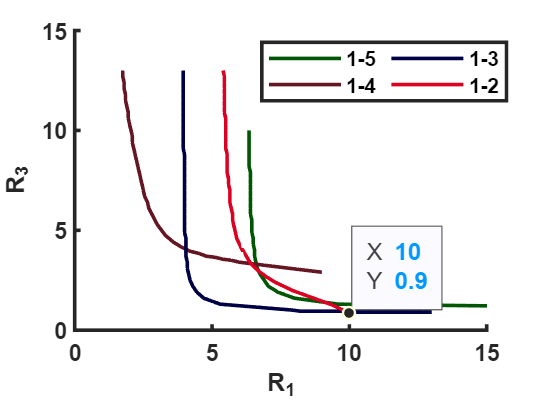




 
plot(x5,y5,'color',[200, 50, 0]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','1-6');


plot(x4,y4,'color',[0, 87, 3]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','1-5');

plot(x3,y3,'color',[100, 22, 35]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','1-4');

plot(x2,y2,'color',[0, 0, 69]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','1-3');

plot(x1,y1,'color',[221, 0, 35]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','1-2');








set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast','NumColumns',2);
hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end

